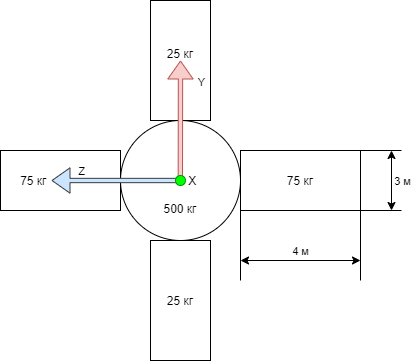

clear all

% Центр
m_c=500

m_c = 500

r_c=1

r_c = 1


% Размеры панелей
a=4

a = 4

b=3

b = 3


% Расстояние от центра панелей до центра масс в плоскости YOZ
d=r_c+a/2

d = 3


% Панели вертикальные
m_v=25

m_v = 25


% Панели горизонтальные
m_h=100-m_v

m_h = 75


% Моменты инерции центра
Jc_x=(2/5)*m_c*r_c^2;
Jc_y=Jc_x;
Jc_z=Jc_x;

% Собственные моменты инерции вертикальных панелей 
Jv_x=m_v*(a^2+b^2)/12

Jv_x = 52.0833

Jv_y=m_v*(b^2)/12

Jv_y = 18.7500

Jv_z=m_v*(a^2)/12

Jv_z = 33.3333


% Собственные моменты инерции горизонтальных панелей 
Jh_x=m_h*(b^2+a^2)/12

Jh_x = 156.2500

Jh_y=m_h*(a^2)/12

Jh_y = 100

Jh_z=m_h*(b^2)/12

Jh_z = 56.2500


% Суммарные моменты инерции по каждой оси
Jx=Jc_x + (2*Jv_x+2*m_v*d^2) +(2*Jh_x+2*m_h*d^2);
Jy=Jc_y + (2*Jv_y+2*m_v*d^2) +(2*Jh_y+2*m_h*d^2);
Jz=Jc_z + (2*Jv_z+2*m_v*d^2) +(2*Jh_z+2*m_h*d^2);

J=[Jx;Jy;Jz]

J = 	1.0e+03 *

    2.4167
    2.2375
    2.1792



save('params',"J","Jx","Jy","Jz")